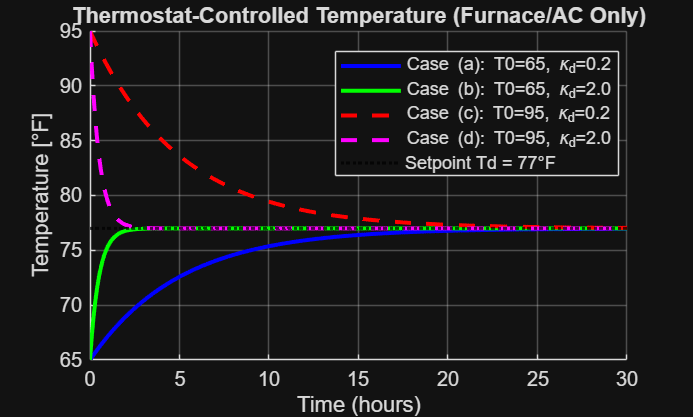

% rk4_thermostat_compare.m
clc;
clear;

% Simulation parameters
Td = 77;             % Thermostat setpoint
t0 = 0;
tf = 30;
dt = 0.1;
t = t0:dt:tf;
N = length(t);

% Case definitions
cases = {
    65, 0.2, 'b-', 'Case (a): T0=65, \kappa_d=0.2';
    65, 2.0, 'g-', 'Case (b): T0=65, \kappa_d=2.0';
    95, 0.2, 'r--','Case (c): T0=95, \kappa_d=0.2';
    95, 2.0, 'm--','Case (d): T0=95, \kappa_d=2.0';
};

% Prepare plot
figure;
hold on;

% Loop through cases
for i = 1:4
    T0 = cases{i,1};
    kappa_d = cases{i,2};
    style = cases{i,3};
    label = cases{i,4};

    k = kappa_d;

    % Initialize temperature vector
    T = zeros(1, N);
    T(1) = T0;

    % Define the differential equation
    dTdt = @(t, T) -k * (T - Td);

    % RK4 integration
    for j = 1:N-1
        tj = t(j);
        Tj = T(j);

        k1 = dt * dTdt(tj, Tj);
        k2 = dt * dTdt(tj + dt/2, Tj + k1/2);
        k3 = dt * dTdt(tj + dt/2, Tj + k2/2);
        k4 = dt * dTdt(tj + dt, Tj + k3);

        T(j+1) = Tj + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
    end

    % Plot the result
    plot(t, T, style, 'LineWidth', 2, 'DisplayName', label);
end

% Finalize plot
yline(Td, 'k:', 'LineWidth', 1.5, 'DisplayName', 'Setpoint Td = 77°F');
xlabel('Time (hours)');
ylabel('Temperature [°F]');
title('Thermostat-Controlled Temperature (Furnace/AC Only)');
legend('Location', 'best');
grid on;